# Mitsubitshi. 3R Manipulator

Group: Z (Javier Cabrera, Júlia Gasull)

Link: [https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

## (0) Statement

**Given the following 3R robot and the Standard Frame attachment where L1+L2=1, L3=2, L4=3**

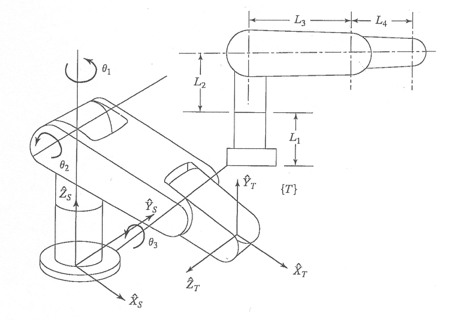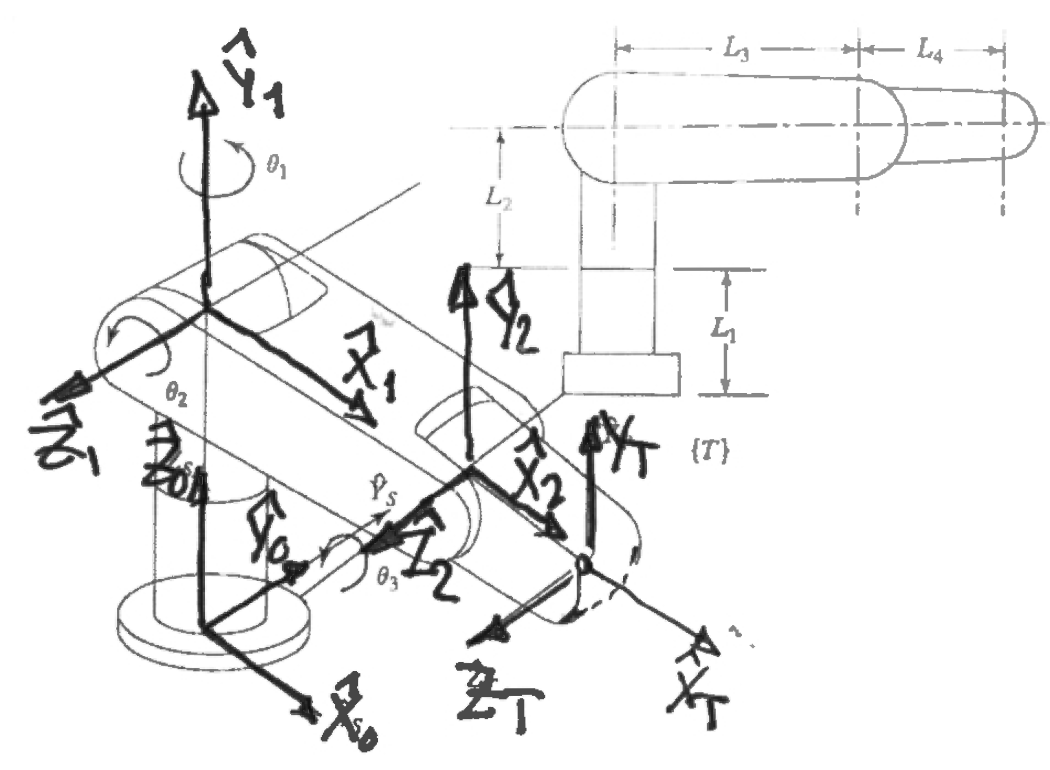

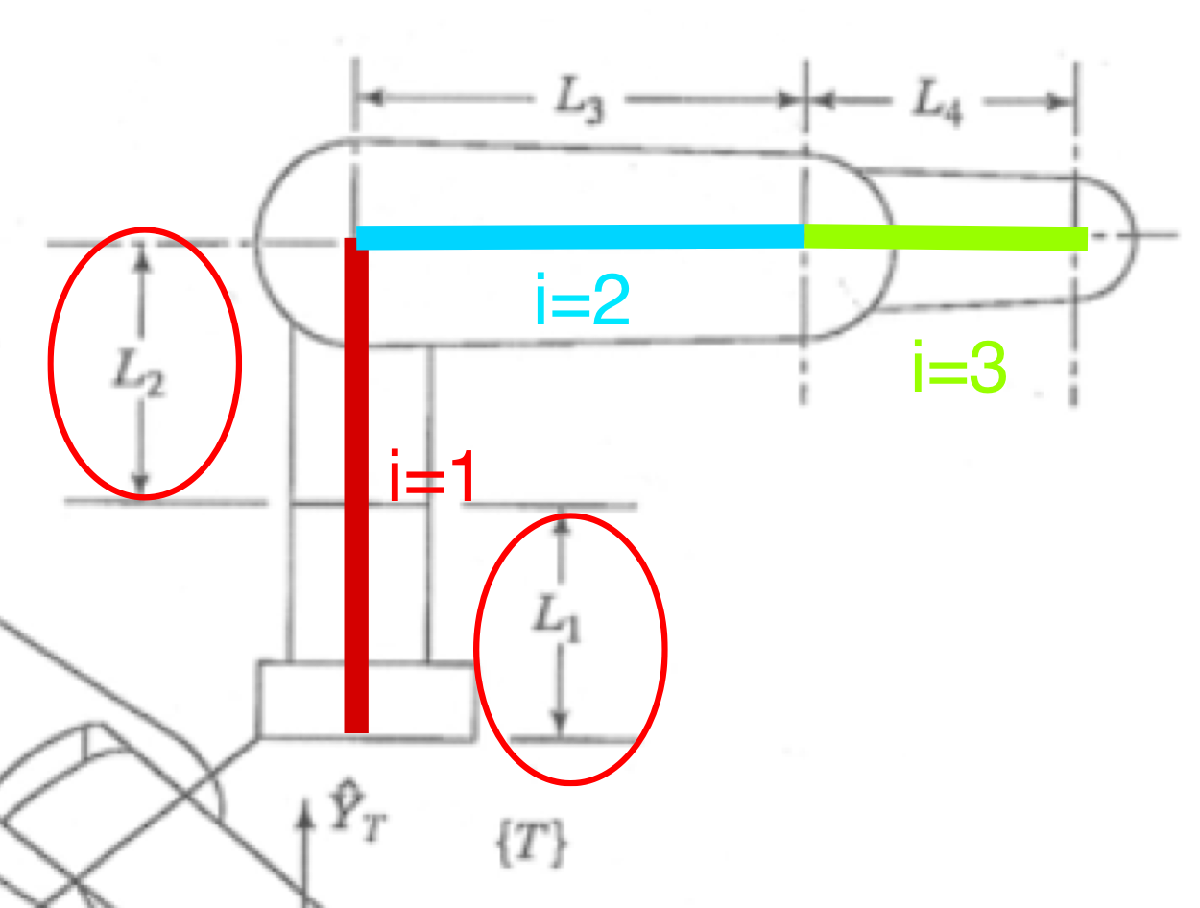

## (1) Neighbouring homogeneous transformation

**Derive the DH parameters table and the neighbouring homogeneous transformation **$${}_i^{i - 1}T$$**matrices, for i=1,2,3, as functions of the joint angles**

clear
mdl_3link3d
R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, fastRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


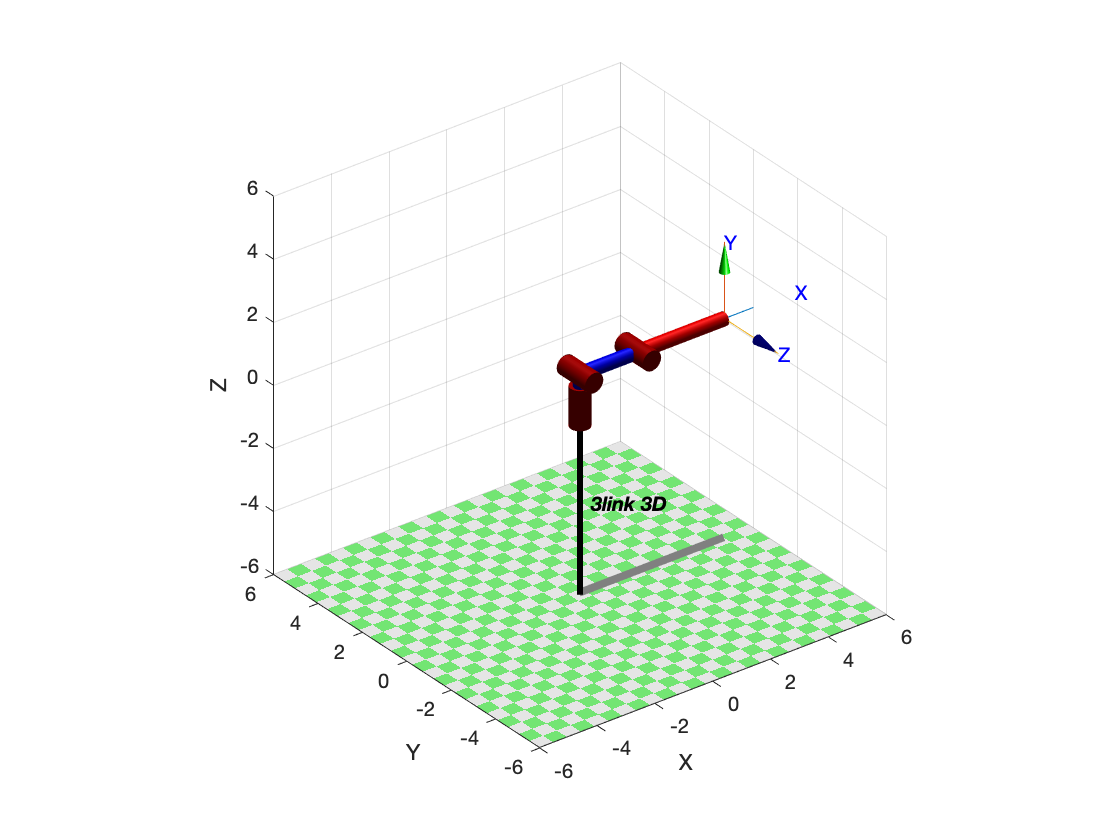

R3.plot([0 0 0])

syms theta_1 theta_2 theta_3 L_2 L_3 L_4 real
T_0_1 = transl(0,0,L_2)*trotz(theta_1);
T_1_2 = trotx(pi/2)*trotz(theta_2)*transl(L_3,0,0);
T_2_3 = trotz(theta_3)*transl(L_4,0,0);

## (2) Forward kinematics

**Implement the forward kinematics, that is, **$${}_3^0T({\theta _1},{\theta _2},{\theta _3})$$**.**

### Symbolic

T_0_3 = simplify(T_0_1*T_1_2*T_2_3)

$$T\_0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{2}+L_{4}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{3}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{4}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{3}\,\cos\left(\theta_{2}\right) \end{array}$$

### Numerical

Default values:

L2 = 1; R3.links(1, 1).d = L2;
L3 = 2; R3.links(1, 2).a = L3;
L4 = 3; R3.links(1, 3).a = L4;

Our destiny point:

theta1 = deg2rad(-67.5)

theta1 = -1.1781

theta2 = deg2rad(70.5)

theta2 = 1.2305

theta3 = deg2rad(-96)

theta3 = -1.6755

T_0_1 = transl(0,0,L2)*trotz(theta1);
T_1_2 = trotx(pi/2)*trotz(theta2)*transl(L3,0,0);
T_2_3 = trotz(theta3)*transl(L4,0,0);

T_0_3 = T_0_1*T_1_2*T_2_3;

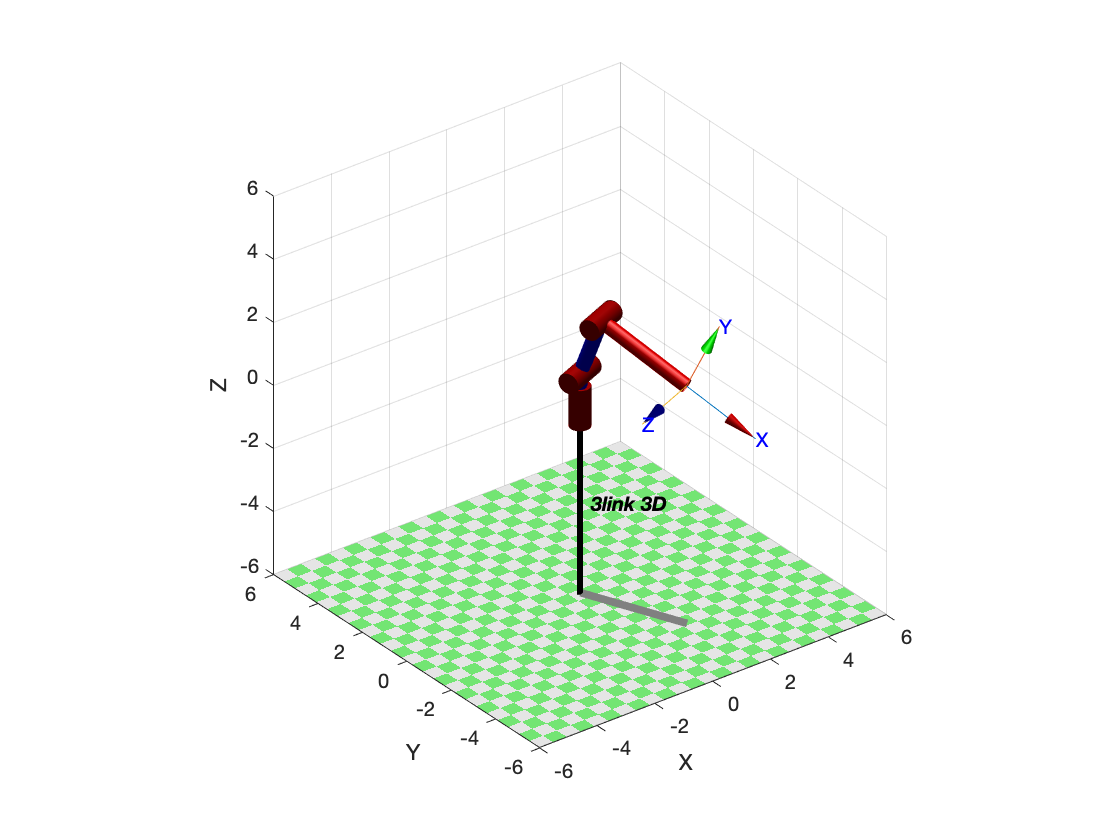

P_destiny = T_0_3 * [0 0 0 1]';
R3.plot([theta1 theta2 theta3],'trail','--','jaxes','zoom',0.1)

T = R3.fkine([theta1 theta2 theta3]);

### Comparison

comparison = [P_destiny(1:3,:) [T.t]] 

comparison =     1.2917    1.2917
   -3.1184   -3.1184
    1.5937    1.5937


## (3) Inverse kinematics

**Implement your own inverse Kinematics**

We start from a vertical point of view. We will move the destination point so that theta1 (q1) is 0 and we can apply the equations seen in theory. To be able to put ourselves in this situation, we must find out what the degrees of rotation of q1 are and we will rotate our destination point based on that angle.

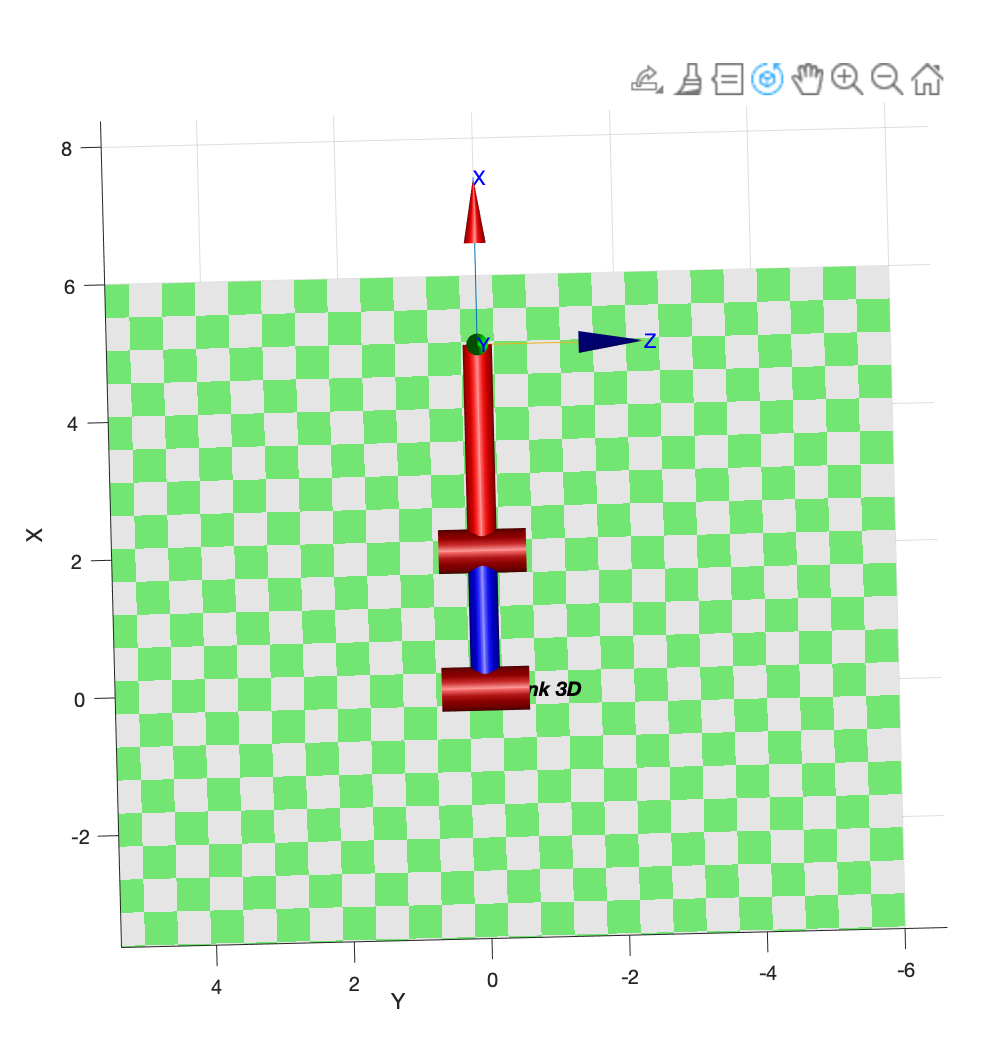

### Symbolic

syms x_p y_p z_p L_2 L_3 L_4 theta_1 theta_2 theta_3 beta gamma real
theta_1 = atan2(y_p,x_p)

$$theta\_1 = \text{atan2}\left(y_{p},x_{p}\right)$$

P =[x_p y_p z_p]*rotz(theta_1) + [0 0 -L_2]

$$P = \left(\begin{array}{ccc} \frac{{x_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}+\frac{{y_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}} & 0 & z_{p}-L_{2} \end{array}\right)$$

theta_3 = acos( ((P(1)^2 + P(3)^2 ) - (L_3^2 + L_4^2)) / (2*L_3*L_4) );
beta = atan2(P(3),P(1))

$$beta = \text{atan2}\left(z_{p}-L_{2},\frac{{x_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}+\frac{{y_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}\right)$$

gamma = acos( (P(1)^2 + P(3)^2 + L_3^2 - L_4^2) / (2*L_3*sqrt(P(1)^2+P(3)^2)) )

$$gamma = \begin{array}{l} \mathrm{acos}\left(\frac{\sigma_{1}+{L_{3}}^{2}-{L_{4}}^{2}+{\left(L_{2}-z_{p}\right)}^{2}}{2\,L_{3}\,\sqrt{\sigma_{1}+{\left(L_{2}-z_{p}\right)}^{2}}}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{{x_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}+\frac{{y_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}\right)}^{2} \end{array}$$

theta_2 = beta + gamma

$$theta\_2 = \begin{array}{l} \mathrm{acos}\left(\frac{{\sigma_{1}}^{2}+{L_{3}}^{2}-{L_{4}}^{2}+{\left(L_{2}-z_{p}\right)}^{2}}{2\,L_{3}\,\sqrt{{\sigma_{1}}^{2}+{\left(L_{2}-z_{p}\right)}^{2}}}\right)+\text{atan2}\left(z_{p}-L_{2},\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{x_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}}+\frac{{y_{p}}^{2}}{\sqrt{{x_{p}}^{2}+{y_{p}}^{2}}} \end{array}$$

### Numerical

xp = P_destiny(1);  yp = P_destiny(2);  zp = P_destiny(3);
new_theta1 = atan2(yp,xp)

new_theta1 = -1.1781

P =[xp yp zp]*rotz(new_theta1) + [0 0 -L2]

P =     3.3754    0.0000    0.5937


new_theta3 = acos( ((P(1)^2 + P(3)^2 ) - (L3^2 + L4^2)) / (2*L3*L4) );
new_theta3 = -new_theta3 % in our case --> we pick the negative one

new_theta3 = -1.6755

new_beta = atan2(P(3),P(1))

new_beta = 0.1741

new_gamma = acos( (P(1)^2 + P(3)^2 + L3^2 - L4^2) / (2*L3*sqrt(P(1)^2+P(3)^2)) )

new_gamma = 1.0563

new_theta2 = new_beta + new_gamma

new_theta2 = 1.2305

### Comparison

comparison = [theta1 new_theta1;theta2 new_theta2;theta3 new_theta3]

comparison =    -1.1781   -1.1781
    1.2305    1.2305
   -1.6755   -1.6755
